1)

    Probability of rolling snake eyes vs rolling sevens:

clc; close all; clear all;
pSnakeEyes = (1/6)*(1/6);
rat(pSnakeEyes)

ans = '0 + 1/(36)'

dice1 = [1,2,3,4,5,6];
dice2 = [1,2,3,4,5,6];
sevensPossible = 0;
for i=1:length(dice1)
    for j=1:length(dice2)
        if (dice1(i)+dice2(j)==7)
            sevensPossible = sevensPossible + 1;
        end
    end
end
pSevens = sevensPossible/36;
rat(pSevens)

ans = '0 + 1/(6)'

pRatio = pSnakeEyes/sevensPossible;
rat(pRatio)

ans = '0 + 1/(216)'

2) Convolution operator to determine the probability of the sum of 2 six-sided die.

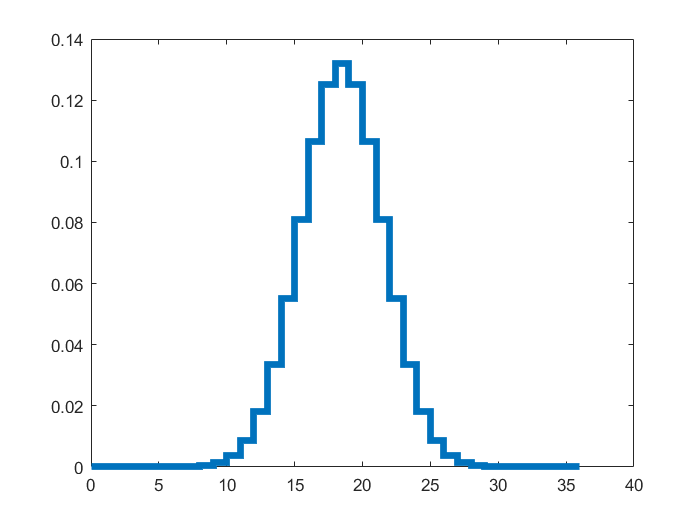

x = 0:36;
bin = makedist("Binomial",'N',36);
stairs(x,pdf(bin,x),"LineWidth",4);

3) Mean and variance of distribution:

m = mean(bin)

m = 18

v = var(bin)

v = 9

4) Average of ten dice:

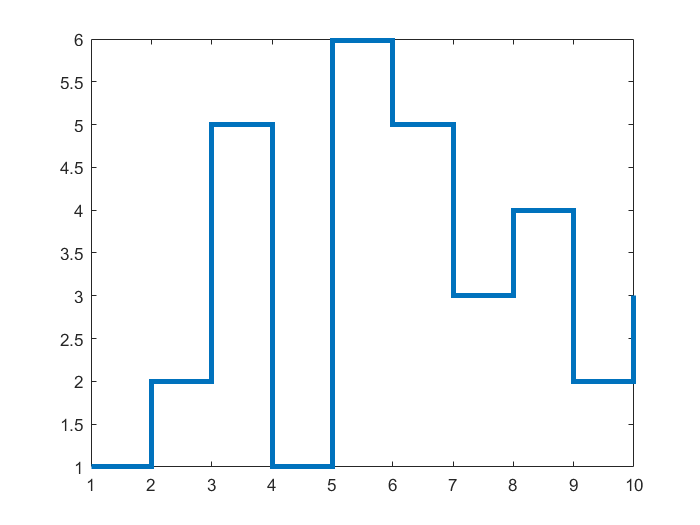

dice1 = [1,2,3,4,5,6];
avg = 0;
x = 1:10;
for i=1:10
    currentRoll = dice1(randi([1,6],1,1));
    avg = avg + currentRoll;
    y(i) = currentRoll;
end
stairs(x,y,"LineWidth",3);


avg

avg = 32

I think it is as after running the above section multiple times, the average stays within the ballpark of 30 and the distribution seems to vary as expected with each run.

5) 

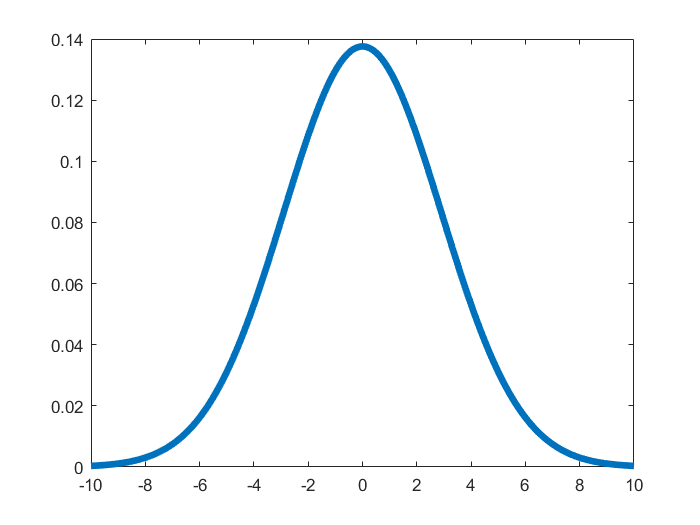

x = linspace(-10,10,1000);
gaus1 = makedist("Normal",'mu',0,'sigma',2.9);
gaus2 = makedist("Normal",'mu',0.8,'sigma',8.4);
gaus3 = makedist("Normal",'mu',-1,'sigma',5.5);

plot(x,pdf(gaus1,x),"LineWidth",4);

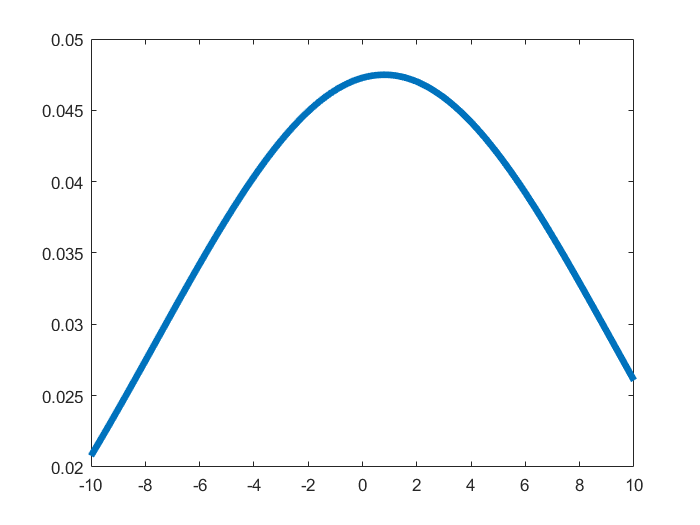

plot(x,pdf(gaus2,x),"LineWidth",4);

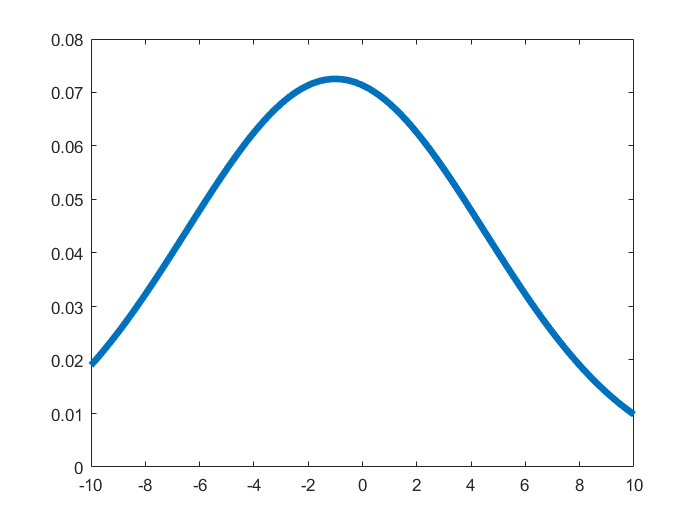

plot(x,pdf(gaus3,x),"LineWidth",4);

As you can see above, the left and right sides of the gaussian distributions are small and the center is large, therefore if you add the distributions together, you should see this pattern continue. (I was planning on showing this via adding the distributions together however matlab does not seem to want to let me do that)